# Exercício 2

## Projete os seguintes filtros digitais usando a janela de Kaiser:

## a) Filtro passa-baixas:


$$\\
A_{p} = 1 [dB]\\
A_{r} = 40 [dB]\\
\Omega_{p} = 1000 [rad/s]\\
\Omega_{r} = 1200 [rad/s]\\
\Omega_{a} = 5000 [rad/s]
$$


Queremos encontrar o valor de $h[n]$ tal que:


$$h[n] = h_{ideal}[n] \cdot  w_{kaiser}[n]$$


Portanto devemos iniciar encontrando os parâmetros que definam $w_{kaiser}[n]$, mas para isso é necessário compreender a forma do nosso filtro ideal:

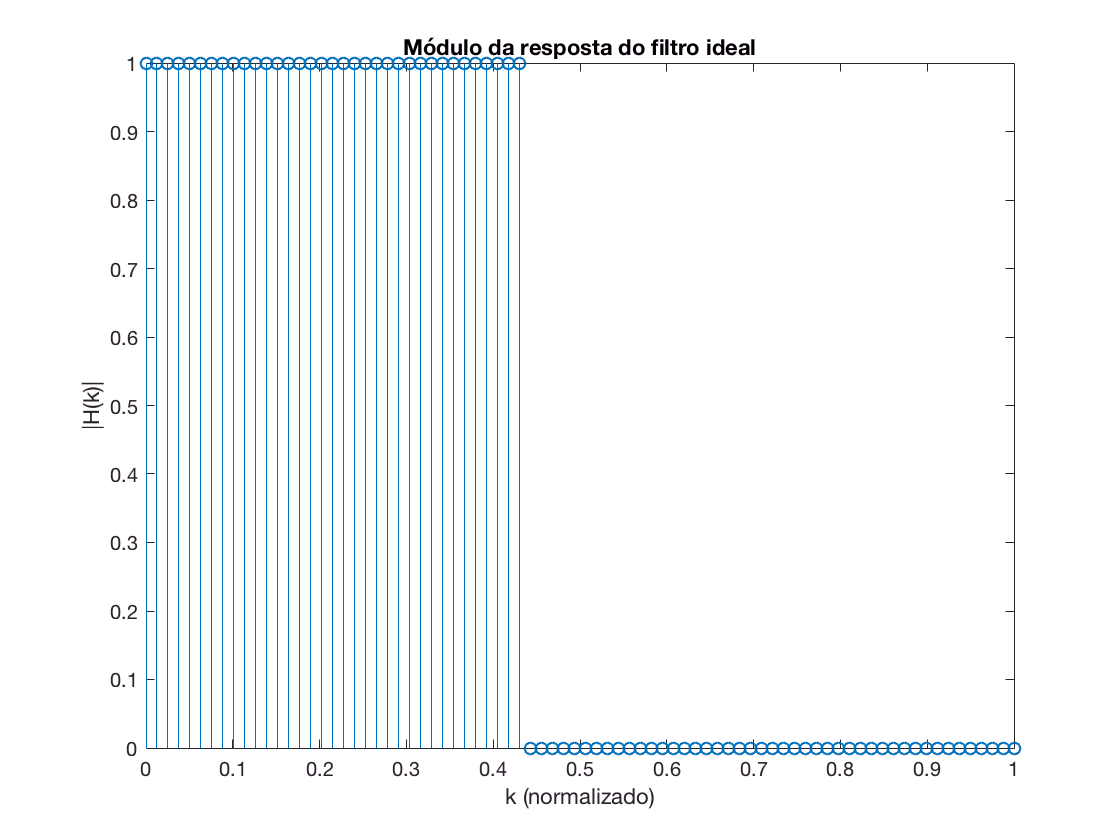

% Parâmetros 
A_p      =  1; % dB
A_r      = 40; % dB
Omega_p =  1000; % rad/s
Omega_r =  1200; % rad/s
Omega_a  = 5000; % rad/s freq. angula de amostragem

% Normalização dos parâmetros
K = (2*pi)/Omega_a;

w_p = Omega_p*K;
w_r = Omega_r*K;
dw = w_r-w_p; % banda de transição
w_c = w_p+dw/2; % frequência de corte a ser utilizada para janela de kaiser

w = linspace(0,pi,80);

ideal = 1*(w < w_c)+0*(w>=w_c);
stem(w/pi, ideal)
title('Módulo da resposta do filtro ideal')
xlabel('k (normalizado)')
ylabel('|H(k)|')

OBS: Vale observar que nem a janela nem o número de pontos aqui utilizado não é igual ao que será utilizado no filtro final.

Outros parâmetro necessário à definição da janela de Kaiser é o $\delta$, portanto:

delta = min(10^(-A_p/20), 10^(-A_r/20))

delta = 0.0100

Portanto, na definição da janela de Kaiser utilizaremos:

a = A_r;
B = 0.5842*(a - 21)^(0.4)+ 0.07886*(a - 21);
D = (a-7.95)/14.36;
L = (pi * D)/(dw);
N = round(2*L + 1);

O que nos dará a seguinte janela de Kaiser:

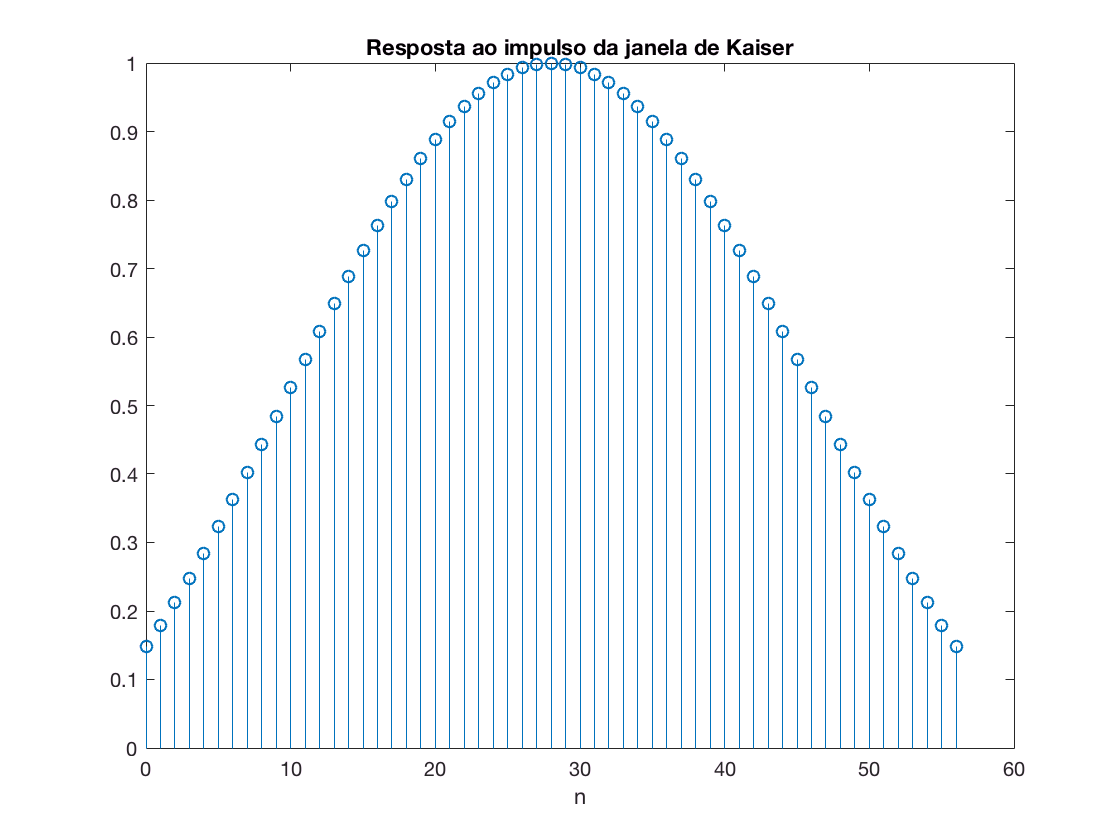

wkaiser = kaiser(N, B);
k = 0:N-1;
stem(k, wkaiser)
title('Resposta ao impulso da janela de Kaiser')
xlabel('n')

Agora que temos a nossa janela de Kaiser desejada, podemos utilizar uma função que utilize essa janela para gerar um filtro FIR passa-baixas:

w_c_n  = w_c/pi; % de 0 a 2*pi para 0 a 1
h = fir1(N-1, w_c_n, wkaiser);
figure(1)
stem(k, h)
title('Resposta ao impulso do filtro passa-baixas')
xlabel('n')

Que, no domínio da frequência, é representada pelo seguinte gráfico:

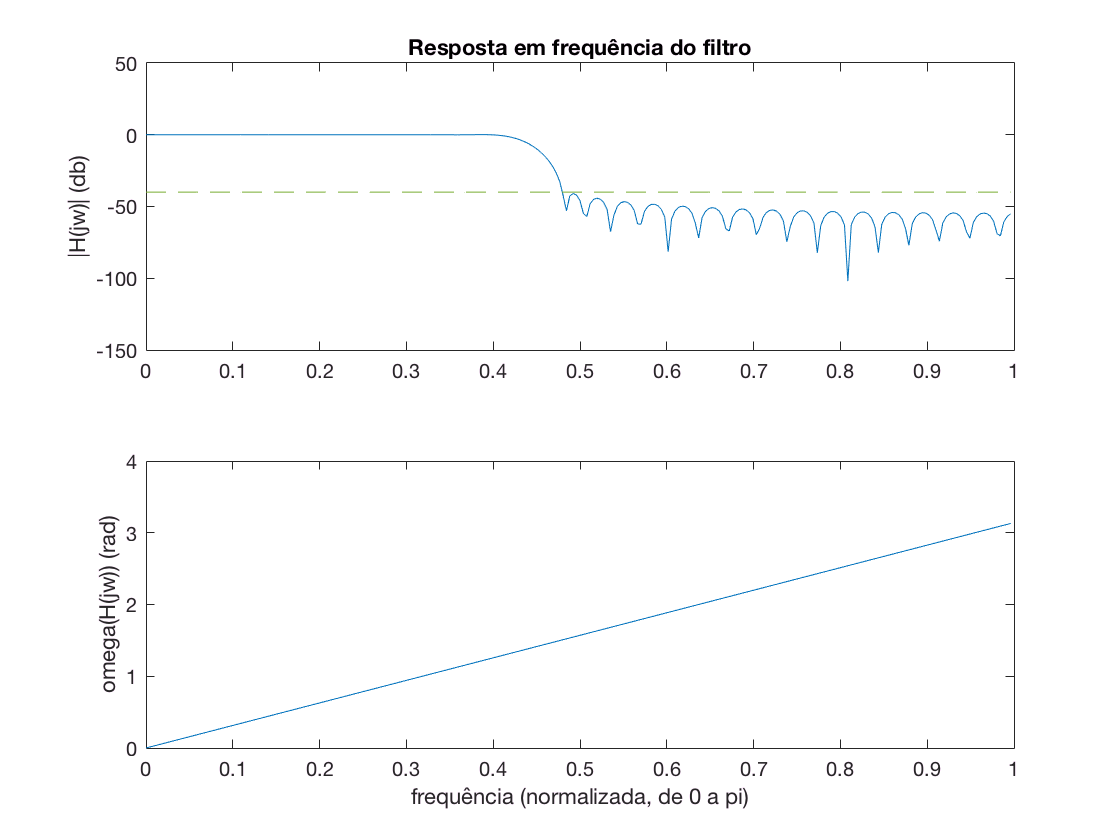

[H, omega] = freqz(h, 1, 256);
mag = 20*log10(abs(H));
spec40db = -A_r*ones(256);
figure(2)
subplot(2,1,1); grid
plot(omega/pi, mag, omega/pi, spec40db, '--') % Especificação de atenuação do filtro
title('Resposta em frequência do filtro')
ylabel('|H(jw)| (db)')
subplot(2,1,2); grid
plot(omega/pi, omega)
ylabel('omega(H(jw)) (rad)')
xlabel('frequência (normalizada, de 0 a pi)')

No gráfico acima podemos observar que o nosso filtro está de acordo com a especificação desejada.

## b) Filtro passa-altas


$$\\
A_{p} = 1 [dB]\\
A_{r} = 40 [dB]\\
\Omega_{r} = 1000 [rad/s]\\
\Omega_{p} = 1200 [rad/s]\\
\Omega_{a} = 5000 [rad/s]
$$


Esse filtro é análogo ao implementado acima, apresentando os mesmos parâmetros para o cálculo da janela de Kaiser, sendo necessário alterar somente os parâmetros da função *fir1*:

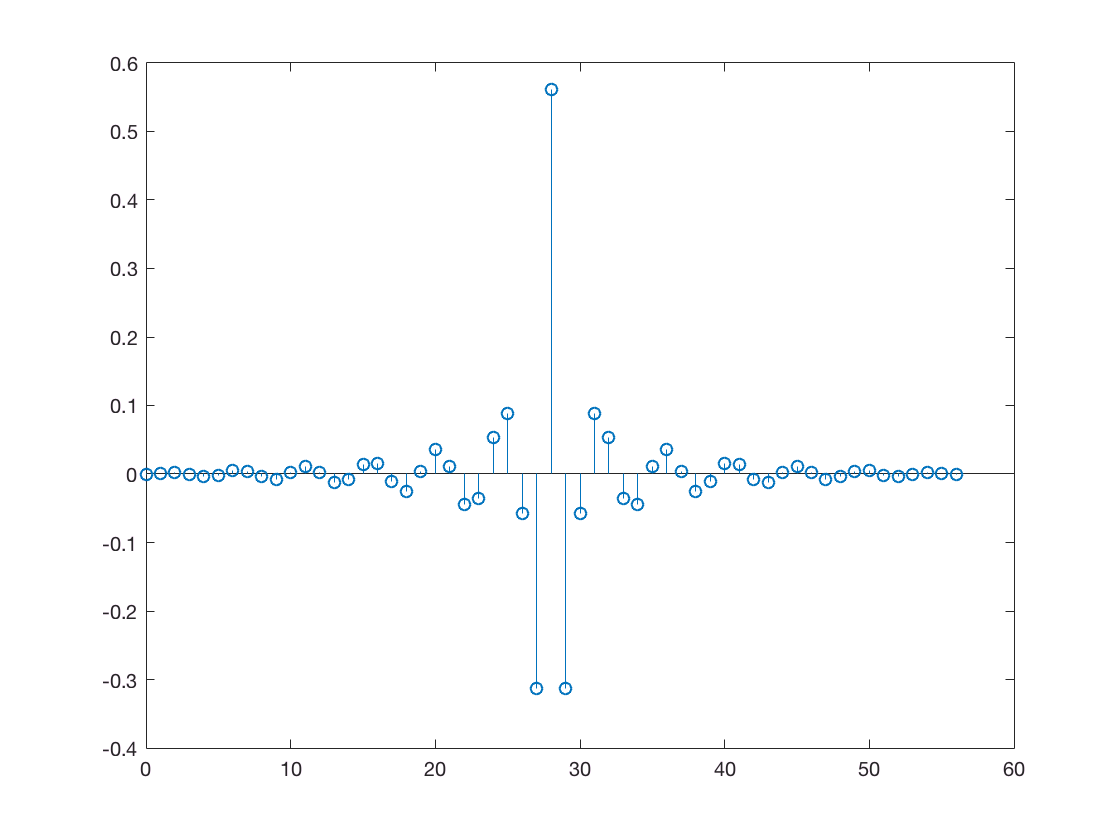

h2 = fir1(N-1, w_c_n, 'high', wkaiser);
figure(3)
stem(k, h2)

title('Resposta ao impulso do filtro passa-altas')
xlabel('n')

Que gera a seguinte resposta em frequência:

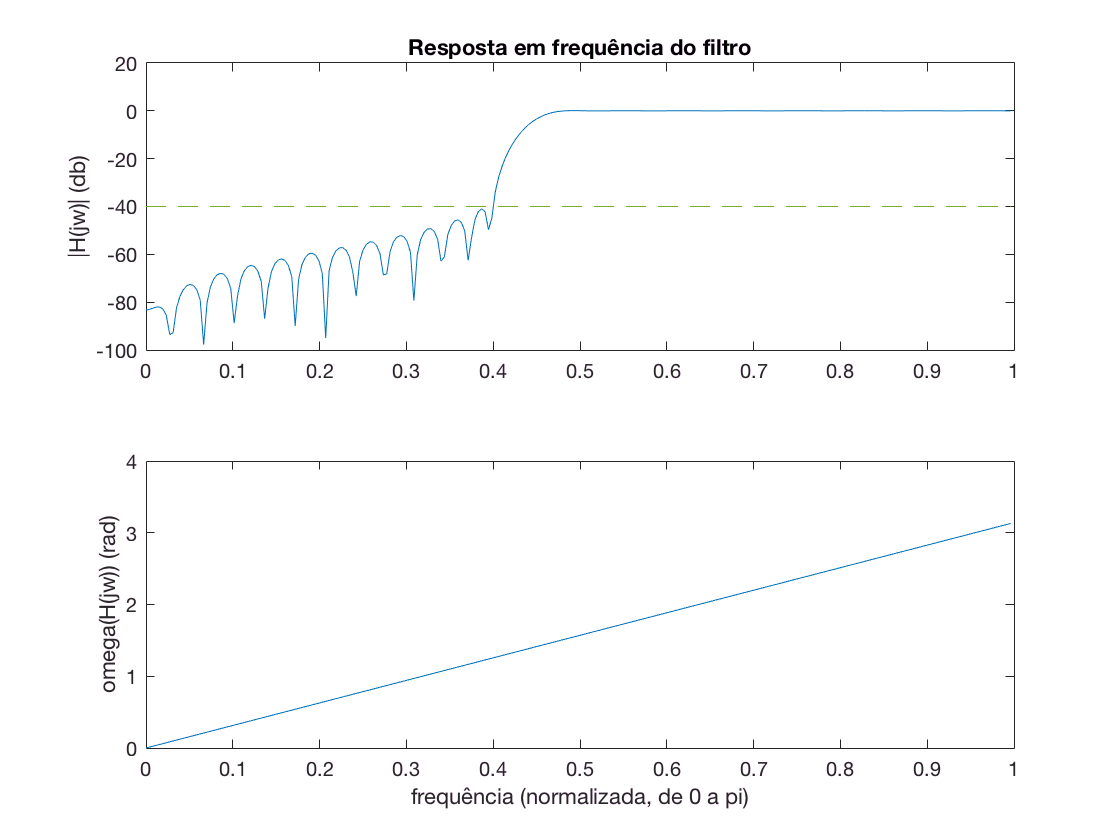

[H, omega] = freqz(h2, 1, 256);
mag = 20*log10(abs(H));
spec40db = -A_r*ones(256);
figure(4)
subplot(2,1,1); grid
plot(omega/pi, mag, omega/pi, spec40db, '--') % Especificação de atenuação do filtro
title('Resposta em frequência do filtro')
ylabel('|H(jw)| (db)')
subplot(2,1,2); grid
plot(omega/pi, omega)
ylabel('omega(H(jw)) (rad)')
xlabel('frequência (normalizada, de 0 a pi)')